clear all
data = readtable("G20CrNi2Mo Bearing Steel Data_Zhao.xlsx");

stress_data = data.ContactStressAmplitude_MPa_;
life_data = data.NumberOfCycles;

% matlab mle returns a - scale parameter and b - shape parameter
stress_levels = unique(stress_data);
num_stress_levels = numel(stress_levels);

N = 5000; % Number of trials at each sample size

% Store results for each stress level
results_Weibull_all = cell(num_stress_levels, 1);
perchange_Weibull_all = cell(num_stress_levels, 1);
results_Lognormal_all = cell(num_stress_levels, 1);
perchange_Lognormal_all = cell(num_stress_levels, 1);

for s = 1:num_stress_levels

    analysis_stress = stress_levels(s);
    analysis_life = life_data(stress_data == analysis_stress);
    num_observations = numel(analysis_life);

    fprintf('\nAnalysing stress level: %g MPa (%d observations)\n', analysis_stress, num_observations);
    sample_size_tests = 2:num_observations; % for testing at sample sizes from 2 to the number of obsrevations (14 for bearing steel)
    x = numel(sample_size_tests);

    % 2P Weibull results
    mu_scale = zeros(x, 1);
    mu_shape = zeros(x, 1);
    mu_B1 = zeros(x, 1);
    sigma_B1 = zeros(x, 1);
    perchange_scale = zeros(x, 1);
    perchange_shape = zeros(x, 1);
    perchange_B1 = zeros(x, 1);

    % 2P lognormal results
    mu_lognormal = zeros(x, 1);
    sigma_lognormal = zeros(x, 1);
    mu_B1_lognormal = zeros(x, 1);
    sigma_B1_lognormal = zeros(x, 1);
    perchange_mu = zeros(x, 1);
    perchange_sigma = zeros(x, 1);
    perchange_B1_lognormal = zeros(x, 1);

    for m = min(sample_size_tests):max(sample_size_tests)
        %m
        % pre-allocate arrays to store the parameters corresponding to each trial
        % 2P weibull trial results
        shape_m = zeros(N, 1); % arrays reinitialised before each run
        scale_m = zeros(N, 1);
        B1_m = zeros(N, 1);

        % 2P lognormal trial results
        mu_m = zeros(N, 1);
        sigma_m = zeros(N, 1);
        B1_lognormal_m = zeros(N, 1);
        k = 0; % tests for at least two unique samples in each trial, rejects random sample that doesn't match this condition
        while k < N
            randlives_k = datasample(analysis_life, m, 'Replace', true);
            if numel(unique(randlives_k)) >= 2
                k = k + 1;
                % run mle for and store paramaters for 2P weibull
                params_weibull_k = mle(randlives_k, "distribution", "Weibull");
                scale_m(k) = params_weibull_k(1);
                shape_m(k) = params_weibull_k(2);
                B1_m(k) = scale_m(k) * (-log(0.99))^(1 / shape_m(k));

                % run mle for and store paramaters for 2P lognormal
                params_log_k = mle(randlives_k, "distribution", "Lognormal");
                mu_m(k) = params_log_k(1);
                sigma_m(k) = params_log_k(2);
                B1_lognormal_m(k) = logninv(0.01, mu_m(k), sigma_m(k));
            end
        end
        % outputs the statistics for the estimated parameters and B1 life at
        % each sample size
        mu_scale(m -1) = mean(scale_m);
        mu_shape(m-1) = mean(shape_m);
        mu_B1(m-1) = mean(B1_m);
        sigma_B1(m-1) = std(B1_m);

        mu_lognormal(m-1) = mean(mu_m);
        sigma_lognormal(m-1) = mean(sigma_m);
        mu_B1_lognormal(m-1) = mean(B1_lognormal_m);
        sigma_B1_lognormal(m-1) = std(B1_lognormal_m);

        if m > 2
            % find the percentage change in the mean shape and scale parameters from the previous ones
            % for weibull
            perchange_scale(m-1) = 100 * abs(mu_scale(m-1) - mu_scale(m-2)) / mu_scale(m-2);
            perchange_shape(m-1) = 100 * abs(mu_shape(m-1) - mu_shape(m-2)) / mu_shape(m-2);
            perchange_B1(m-1) = 100 * abs(mu_B1(m-1) - mu_B1(m-2)) / mu_B1(m-2);
            % for lognormal
            perchange_mu(m-1) = 100 * abs(mu_lognormal(m-1) - mu_lognormal(m-2)) / abs(mu_lognormal(m-2));
            perchange_sigma(m-1) = 100 * abs(sigma_lognormal(m-1) - sigma_lognormal(m-2)) / abs(sigma_lognormal(m-2));
            perchange_B1_lognormal(m-1) = 100 * abs(mu_B1_lognormal(m-1) - mu_B1_lognormal(m-2)) / abs(mu_B1_lognormal(m-2));
        end

    end

    %size(mu_scale)
    %indsample_size_tests = sample_size_tests(2:x)
    sample_size_tests = sample_size_tests';

    % 2P weibull results
    results_Weibull = table(sample_size_tests, mu_scale, mu_shape, mu_B1, sigma_B1);
    perchange_Weibull = table(sample_size_tests,perchange_scale, perchange_shape, perchange_B1);
    % 2P lognormal results
    results_Lognormal = table(sample_size_tests, mu_lognormal, sigma_lognormal, mu_B1_lognormal, sigma_B1_lognormal);
    perchange_Lognormal = table(sample_size_tests, perchange_mu, perchange_sigma, perchange_B1_lognormal);

    % Store results for this stress level
    results_Weibull_all{s} = results_Weibull;
    perchange_Weibull_all{s} = perchange_Weibull;

    results_Lognormal_all{s} = results_Lognormal;
    perchange_Lognormal_all{s} = perchange_Lognormal;
    
end


Analysing stress level: 4900 MPa (14 observations)

Analysing stress level: 5500 MPa (14 observations)

Analysing stress level: 6100 MPa (14 observations)

Analysing stress level: 6700 MPa (14 observations)


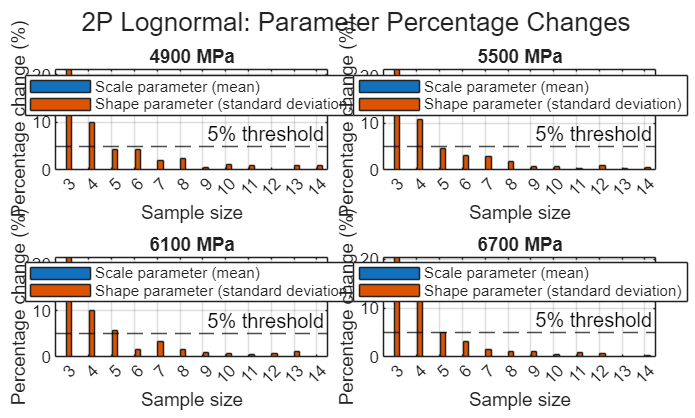



figure('Name','2P Lognormal Parameter Percentage Changes');
tiledlayout(2,2,'TileSpacing','compact','Padding','compact');

for s = 1:num_stress_levels
    results = perchange_Lognormal_all{s};
    sample_size_tests = results.sample_size_tests;
    nexttile;
    bar(sample_size_tests(2:end), [results.perchange_mu(2:end),results.perchange_sigma(2:end)], 'grouped');
    hold on;
    yline(5, 'k--', '5% threshold');
    xlabel('Sample size');
    ylabel('Percentage change (%)');
    title(sprintf('%g MPa', stress_levels(s)));
    legend('Scale parameter (mean)', 'Shape parameter (standard deviation)', 'Location', 'best');
    grid on;
    hold off;

end

sgtitle('2P Lognormal: Parameter Percentage Changes');

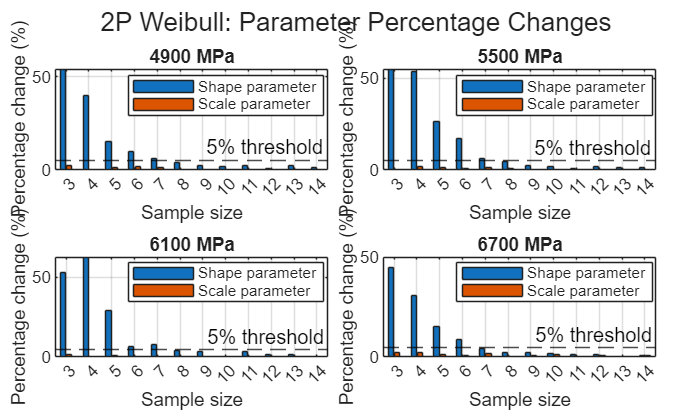


figure('Name','2P Weibull Parameter Percentage Changes');
tiledlayout(2,2,'TileSpacing','compact','Padding','compact');

for s = 1:num_stress_levels
    results = perchange_Weibull_all{s};
    sample_size_tests = results.sample_size_tests;
    nexttile;
    bar(sample_size_tests(2:end), [results.perchange_shape(2:end), results.perchange_scale(2:end)], 'grouped');
    hold on;
    yline(5, 'k--', '5% threshold');
    xlabel('Sample size');
    ylabel('Percentage change (%)');
    title(sprintf('%g MPa', stress_levels(s)));
    legend('Shape parameter', 'Scale parameter','Location', 'best');
    grid on;
    hold off;
end

sgtitle('2P Weibull: Parameter Percentage Changes');

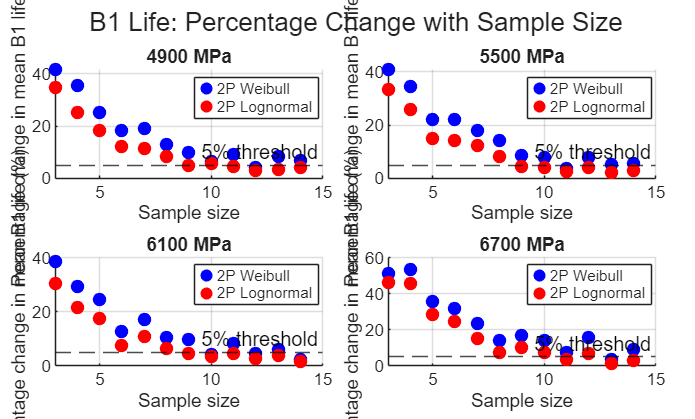


figure('Name','B1 Life Percentage Changes');
tiledlayout(2,2,'TileSpacing','compact','Padding','compact');

for s = 1:num_stress_levels

    results_W = perchange_Weibull_all{s};
    results_L = perchange_Lognormal_all{s};
    sample_size_tests = results_W.sample_size_tests;

    nexttile;
    scatter(sample_size_tests(2:end), results_W.perchange_B1(2:end), 45, 'b', 'filled');
    hold on;
    scatter(sample_size_tests(2:end), results_L.perchange_B1_lognormal(2:end), 45, 'r', 'filled');
    yline(5, 'k--', '5% threshold');
    xlabel('Sample size');
    ylabel('Percentage change in mean B1 life (%)');
    title(sprintf('%g MPa', stress_levels(s)));
    legend('2P Weibull', '2P Lognormal', 'Location', 'best');
    grid on;
    hold off;

end

sgtitle('B1 Life: Percentage Change with Sample Size');

for s = 1:num_stress_levels
    fprintf('\nResults for stress level: %g MPa\n', stress_levels(s));
    disp('Weibull results:')
    disp(results_Weibull_all{s})
    disp('Weibull percentage changes:')
    disp(perchange_Weibull_all{s})
    disp('Lognormal results:')
    disp(results_Lognormal_all{s})
    disp('Lognormal percentage changes:')
    disp(perchange_Lognormal_all{s})
end


Results for stress level: 4900 MPa


Weibull results:


    sample_size_tests     mu_scale     mu_shape      mu_B1        sigma_B1 
    _________________    __________    ________    __________    __________

            2              3.76e+08     6.8006     7.4151e+07    9.8703e+07
            3            3.6636e+08     3.1114     4.3225e+07    6.6685e+07
            4            3.6497e+08     1.8732     2.7887e+07    4.4615e+07
            5            3.6041e+08     1.5816     2.0859e+07    3.0703e+07
            6            3.6745e+08     1.4245     1.7052e+07    2.4672e+07
            7             3.632e+08     1.3335     1.3822e+07    1.8298e+07
            8            3.6152e+08     1.2795     1.2031e+07    1.5308e+07
            9            3.5978e+08     1.2502     1.0855e+07    1.2805e+07
           10            3.5978e+08     1.2268     1.0145e+07    1.2346e+07
           11            3.5912e+08     1.1987     9.2251e+06    1.0801e+07
           12            3.5813e+08     1.1912     8.8385e+06    9.6052e+06
           

Weibull percentage changes:


    sample_size_tests    perchange_scale    perchange_shape    perchange_B1
    _________________    _______________    _______________    ____________

            2                       0                 0                0   
            3                  2.5639            54.247           41.706   
            4                 0.38052            39.797           35.485   
            5                  1.2482            15.567             25.2   
            6                  1.9529            9.9299           18.252   
            7                  1.1555             6.394           18.946   
            8                  0.4648            4.0459           12.955   
            9                 0.47903            2.2881           9.7742   
           10               0.0022807            1.8715           6.5458   
           11                 0.18288            2.2943           9.0626   
           12                 0.27636           0.62496           4.1908   
           

Lognormal results:


    sample_size_tests    mu_lognormal    sigma_lognormal    mu_B1_lognormal    sigma_B1_lognormal
    _________________    ____________    _______________    _______________    __________________

            2                19.17           0.66177          9.9858e+07           1.1264e+08    
            3               19.155           0.80197          6.5225e+07           7.7819e+07    
            4                19.15           0.88115          4.8792e+07            5.748e+07    
            5               19.153           0.91914          3.9919e+07           4.1989e+07    
            6               19.171           0.95876          3.5057e+07            3.621e+07    
            7               19.162           0.97719          3.1023e+07           2.9736e+07    
            8               19.155            1.0002          2.8384e+07           2.6012e+07    
            9               19.159            1.0049          2.7023e+07           2.3272e+07    
           10      

Lognormal percentage changes:


    sample_size_tests    perchange_mu    perchange_sigma    perchange_B1_lognormal
    _________________    ____________    _______________    ______________________

            2                     0                0                     0        
            3              0.080999           21.185                34.682        
            4              0.025069           9.8733                25.193        
            5              0.016813           4.3117                18.185        
            6              0.093303           4.3107                 12.18        
            7               0.04749           1.9223                11.507        
            8              0.034795           2.3574                 8.508        
            9               0.01779          0.47066                4.7945        
           10             0.0013403           1.2202                5.7175        
           11              0.017766           0.9426                4.5085        
   


Results for stress level: 5500 MPa


Weibull results:


    sample_size_tests     mu_scale     mu_shape      mu_B1        sigma_B1 
    _________________    __________    ________    __________    __________

            2            1.4079e+08      11.31      2.814e+07    3.6164e+07
            3            1.4046e+08     5.0688     1.6584e+07    2.4478e+07
            4            1.3794e+08     2.3534     1.0838e+07    1.7226e+07
            5            1.3984e+08     1.7335     8.4467e+06    1.3124e+07
            6            1.3878e+08     1.4392     6.5754e+06    9.4731e+06
            7            1.3689e+08      1.352     5.3826e+06    7.7624e+06
            8            1.3798e+08     1.2892     4.6208e+06    5.8054e+06
            9            1.3742e+08     1.2572      4.231e+06    4.9953e+06
           10            1.3693e+08     1.2342     3.9061e+06    4.3953e+06
           11            1.3683e+08      1.224     3.7654e+06    4.2111e+06
           12            1.3712e+08     1.1976     3.4676e+06    3.5762e+06
           

Weibull percentage changes:


    sample_size_tests    perchange_scale    perchange_shape    perchange_B1
    _________________    _______________    _______________    ____________

            2                      0                  0                0   
            3                0.22986             55.183           41.064   
            4                  1.799             53.571           34.647   
            5                 1.3815              26.34           22.067   
            6                0.75823             16.978           22.155   
            7                 1.3608              6.057           18.139   
            8                0.79187             4.6435           14.154   
            9                0.40506             2.4863           8.4356   
           10                0.35619             1.8252           7.6784   
           11               0.072242            0.82674           3.6032   
           12                0.21409             2.1566           7.9073   
           

Lognormal results:


    sample_size_tests    mu_lognormal    sigma_lognormal    mu_B1_lognormal    sigma_B1_lognormal
    _________________    ____________    _______________    _______________    __________________

            2               18.197           0.65231          3.7818e+07           4.1368e+07    
            3               18.203           0.79272          2.5222e+07           2.9165e+07    
            4               18.183           0.87766          1.8651e+07           2.1962e+07    
            5               18.209            0.9174          1.5877e+07             1.75e+07    
            6               18.206           0.94502          1.3641e+07           1.3796e+07    
            7                18.19            0.9732          1.1935e+07           1.1699e+07    
            8                 18.2           0.99076          1.0952e+07           9.7216e+06    
            9               18.197           0.99741          1.0442e+07           8.9038e+06    
           10      

Lognormal percentage changes:


    sample_size_tests    perchange_mu    perchange_sigma    perchange_B1_lognormal
    _________________    ____________    _______________    ______________________

            2                      0               0                     0        
            3               0.032752          21.525                33.305        
            4                0.10924          10.714                26.054        
            5                0.14377          4.5284                 14.87        
            6               0.020722          3.0101                14.086        
            7                0.08615          2.9826                12.509        
            8               0.054537          1.8045                8.2339        
            9               0.016086         0.67089                4.6587        
           10               0.017256         0.74252                4.1677        
           11             0.00086058         0.39685                 2.738        
   


Results for stress level: 6100 MPa


Weibull results:


    sample_size_tests     mu_scale     mu_shape      mu_B1        sigma_B1 
    _________________    __________    ________    __________    __________

            2            6.5089e+07     14.333     1.5149e+07    1.7984e+07
            3             6.601e+07      6.765     9.3236e+06    1.2307e+07
            4            6.5956e+07     2.5157     6.6028e+06    9.0365e+06
            5            6.5249e+07     1.7833     4.9719e+06    6.4178e+06
            6              6.54e+07     1.6698     4.3361e+06    5.3568e+06
            7             6.529e+07     1.5396     3.6004e+06    4.1575e+06
            8            6.5459e+07     1.4737     3.2276e+06    3.4974e+06
            9            6.5422e+07     1.4256     2.9176e+06     2.995e+06
           10            6.5029e+07     1.4239      2.798e+06    3.0455e+06
           11            6.5104e+07     1.3791     2.5706e+06    2.3389e+06
           12            6.5202e+07     1.3598     2.4488e+06    2.1954e+06
           

Weibull percentage changes:


    sample_size_tests    perchange_scale    perchange_shape    perchange_B1
    _________________    _______________    _______________    ____________

            2                      0                  0                0   
            3                  1.415             52.801           38.453   
            4                0.08183             62.813           29.182   
            5                 1.0716             29.114           24.699   
            6                0.23055             6.3612           12.789   
            7                 0.1675             7.8006           16.965   
            8                0.25906             4.2778           10.355   
            9               0.057128             3.2634           9.6063   
           10                0.59993            0.12177           4.0971   
           11                0.11513             3.1483           8.1304   
           12                0.14925             1.3946           4.7359   
           

Lognormal results:


    sample_size_tests    mu_lognormal    sigma_lognormal    mu_B1_lognormal    sigma_B1_lognormal
    _________________    ____________    _______________    _______________    __________________

            2                17.52           0.57505          1.9978e+07           2.0165e+07    
            3               17.533           0.69923          1.3879e+07           1.4253e+07    
            4               17.531           0.76916          1.0911e+07           1.1041e+07    
            5               17.518           0.81353          9.0147e+06           8.5148e+06    
            6               17.528           0.82716          8.3214e+06           7.3221e+06    
            7               17.523           0.85517          7.4192e+06           6.1946e+06    
            8               17.527           0.86822           6.956e+06           5.4746e+06    
            9               17.529           0.87751          6.6492e+06           4.9571e+06    
           10      

Lognormal percentage changes:


    sample_size_tests    perchange_mu    perchange_sigma    perchange_B1_lognormal
    _________________    ____________    _______________    ______________________

            2                     0                0                     0        
            3              0.069194           21.595                30.528        
            4             0.0068523               10                21.383        
            5              0.076621            5.769                17.382        
            6              0.060635           1.6749                7.6909        
            7              0.029022           3.3863                10.842        
            8              0.018816           1.5268                6.2426        
            9              0.011189           1.0698                4.4102        
           10                0.0249          0.78775                3.3226        
           11             0.0073369          0.64636                4.4928        
   


Results for stress level: 6700 MPa


Weibull results:


    sample_size_tests     mu_scale     mu_shape      mu_B1        sigma_B1 
    _________________    __________    ________    __________    __________

            2            4.1297e+07     3.2558     6.8357e+06    1.3983e+07
            3             4.031e+07     1.7997     3.3483e+06    9.2632e+06
            4            3.9467e+07      1.247     1.5604e+06    4.9931e+06
            5            3.8884e+07     1.0585     1.0026e+06     3.228e+06
            6            3.8578e+07    0.96387     6.8248e+05    2.0831e+06
            7             3.793e+07    0.92201     5.2375e+05    1.5379e+06
            8            3.8119e+07    0.90008     4.4938e+05    1.1555e+06
            9            3.7888e+07    0.87979     3.7377e+05     8.798e+05
           10             3.748e+07    0.86416     3.2049e+05    6.7228e+05
           11            3.7556e+07    0.85296     2.9709e+05    6.6064e+05
           12            3.7339e+07    0.84062      2.501e+05    4.5365e+05
           

Weibull percentage changes:


    sample_size_tests    perchange_scale    perchange_shape    perchange_B1
    _________________    _______________    _______________    ____________

            2                      0                  0                0   
            3                 2.3921             44.725           51.017   
            4                 2.0907              30.71           53.398   
            5                 1.4755             15.116            35.75   
            6                 0.7874             8.9403           31.926   
            7                 1.6802             4.3428           23.257   
            8                0.49799             2.3781           14.199   
            9                0.60699             2.2548           16.827   
           10                  1.076              1.776           14.254   
           11                0.20293             1.2968           7.3002   
           12                0.57668              1.446           15.818   
           

Lognormal results:


    sample_size_tests    mu_lognormal    sigma_lognormal    mu_B1_lognormal    sigma_B1_lognormal
    _________________    ____________    _______________    _______________    __________________

            2               16.678           0.89908            9.09e+06           1.6483e+07    
            3               16.671             1.083          4.8862e+06           1.1204e+07    
            4               16.675             1.207           2.667e+06           6.6143e+06    
            5               16.668            1.2665          1.9043e+06           4.6252e+06    
            6               16.673            1.3074          1.4349e+06           3.0001e+06    
            7               16.663            1.3285          1.2153e+06           2.1801e+06    
            8               16.678            1.3426          1.1224e+06           1.6767e+06    
            9               16.677            1.3586          1.0092e+06           1.3586e+06    
           10      

Lognormal percentage changes:


    sample_size_tests    perchange_mu    perchange_sigma    perchange_B1_lognormal
    _________________    ____________    _______________    ______________________

            2                     0                0                     0        
            3              0.041883           20.451                46.247        
            4              0.025547           11.457                45.418        
            5              0.043431           4.9305                28.597        
            6              0.029123           3.2259                24.648        
            7              0.055675            1.617                15.302        
            8               0.08515           1.0599                7.6458        
            9             0.0035717           1.1941                10.084        
           10              0.060468          0.60756                7.1684        
           11              0.047851          0.96561                3.7686        
   